**NEWTON METHOD**

%Specifications

 a1 = 1; 
 a2 = 1;
 a3 = 1;

 X1d = 2 ;
 X2d = 1; 
 X3d = 0; %End effector points

**Newton Method  IC: 0 0 0 rad**

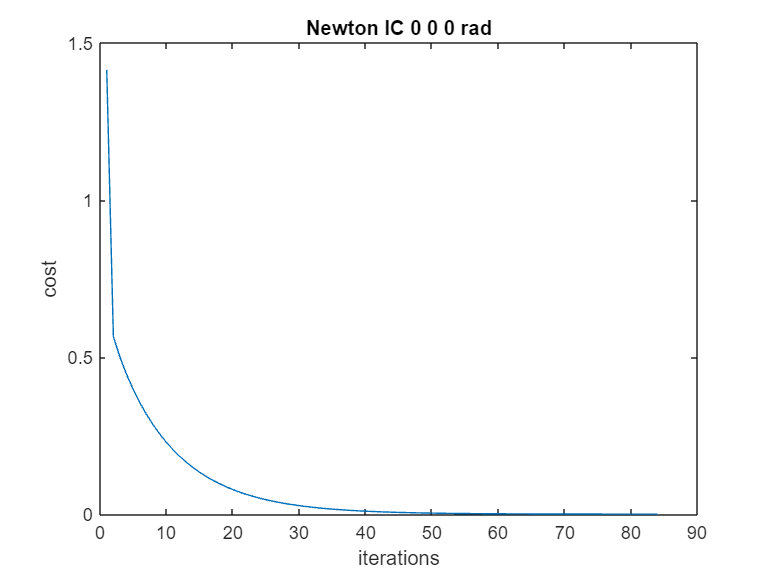

theta_1 = -0.0039

theta_2 = 89.9995

theta_3 = -89.9901

iterations = 84

 theta_in_1 = 0; 
 theta_in_2 = 0;
 theta_in_3 = 0; %Starting point angle

 rate = 1/10;

[theta_1, theta_2 , theta_3, iterations] = NewtonMethod(theta_in_1, theta_in_2, theta_in_3, rate,a1,a2,a3,X1d,X2d,X3d)

**Newton Method  IC: 0 0 0 rad**

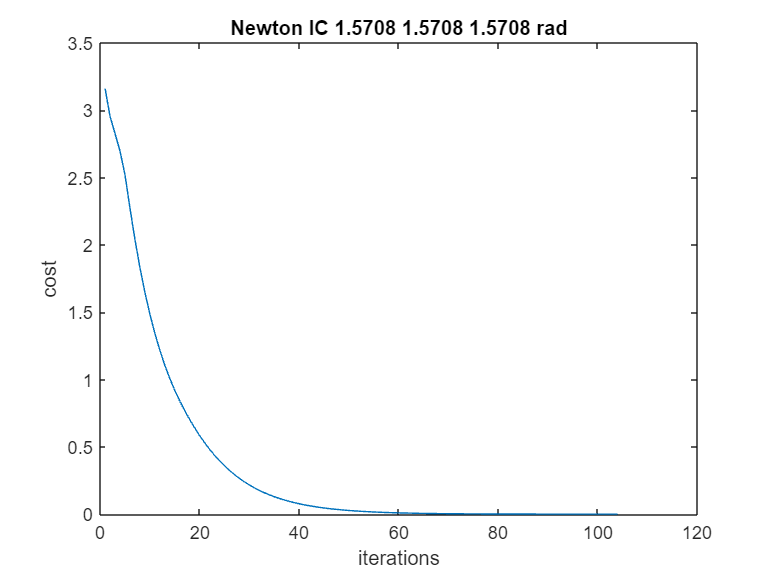

theta_1 = -0.0070

theta_2 = 90.0112

theta_3 = -89.9994

iterations = 104

theta_in_1 = pi/2; 
theta_in_2 = pi/2;
theta_in_3 = pi/2; %Starting point angle

[theta_1, theta_2 , theta_3, iterations] = NewtonMethod(theta_in_1, theta_in_2, theta_in_3, rate,a1,a2,a3,X1d,X2d,X3d)

function [theta_1, theta_2, theta_3, iterations] = NewtonMethod(theta_in_1, theta_in_2, theta_in_3, rate, a1,a2,a3,X1d,X2d,X3d)

     % Counter for number of Iterations
     count = 0;
    
     % Calculate Initial starting points using Forward Kinematics
     X1 = a1*cos(theta_in_1) + a2*cos(theta_in_1+theta_in_2) + a3*cos(theta_in_1+theta_in_2+theta_in_3);
     X2 = a1*sin(theta_in_1) + a2*sin(theta_in_1+theta_in_2) + a3*sin(theta_in_1+theta_in_2+theta_in_3);
     X3 = theta_in_1+theta_in_2+theta_in_3;
    
    
     % Vector matrix of desired location of robotic arm
     end_eff = [X1d;X2d; X3d];
    
     % Vector matrix of starting point of robotic arm
     start_eff = [X1;X2;X3];
    
     % Vector matrix of starting potint angle of robotic arm
     theta_eff = [theta_in_1;theta_in_2;theta_in_3];
    
     % Error related to end effector and starting point
     error = start_eff - end_eff;
    
     % Cost function based on euclidean distance of end effector and starting point
     %cost = (1/2) * (error'*error);
     cost = sqrt((end_eff(1,1)-start_eff(1,1))^2+(end_eff(2,1)-start_eff(2,1))^2);
    
     % Iterating the process and decreasing the cost to reach end end effector
    
     count_array = zeros(1, 1);
     cost_array = zeros(1,1);
    
     while (cost > 0.0001)
    
         theta_1 = theta_eff(1,1);
         theta_2 = theta_eff(2,1);
         theta_3 = theta_eff(3,1);
         sin1 = sin(theta_1);
         sin12 = sin(theta_1+theta_2);
         sin123 = sin(theta_1+theta_2+theta_3);
         cos1 = cos(theta_1);
         cos12 = cos(theta_1 + theta_2);
         cos123 = cos(theta_1+theta_2+theta_3);
    
         X1 = a1*cos1 + a2*cos12 + a3*cos123;
         X2 = a1*sin1 + a2*sin12 + a3*sin123;
         X3 = theta_1+theta_2+theta_3;
    
         start_eff = [X1;X2;X3]; % f(q)
         error = start_eff - end_eff ; % f(q) - xd
    
         Jacobian = [(-a1*sin1 - a2*sin12 - a3*sin123), (-a2*sin12 - a3*sin123), (-a3*sin123);
             (a1*cos1 + a2*cos12 + a3*cos123), (a2*cos12 + a3*cos123), (a3*cos123);
             1, 1, 1];
    
         if cond(Jacobian) > 200
    
             theta_eff = theta_eff + 0.2;
    
             theta_1 = theta_eff(1,1);
             theta_2 = theta_eff(2,1);
             theta_3 = theta_eff(3,1);
             sin1 = sin(theta_1);
             sin12 = sin(theta_1+theta_2);
             sin123 = sin(theta_1+theta_2+theta_3);
             cos1 = cos(theta_1);
             cos12 = cos(theta_1 + theta_2);
             cos123 = cos(theta_1+theta_2+theta_3);
    
             Jacobian = [(-a1*sin1 - a2*sin12 - a3*sin123), (-a2*sin12 - a3*sin123), (-a3*sin123);
                 (a1*cos1 + a2*cos12 + a3*cos123), (a2*cos12 + a3*cos123), (a3*cos123);
                 1, 1, 1];
    
         end
    
         inv_jacob = inv(Jacobian);
         theta_eff = theta_eff - rate*(inv_jacob)*error;     % qk+1 = qk-lr*inv(j)*(f(q)-xd)
         cost = sqrt((end_eff(1,1)-start_eff(1,1))^2+(end_eff(2,1)-start_eff(2,1))^2) ;% Euclidean distance
         count = count + 1; % Counting Iterations
         count_array(count) = count;
         cost_array(count) = cost;
    
     end
    
     theta_eff = theta_eff*180/pi;

     theta_1 = theta_eff(1);
     theta_2 = theta_eff(2);
     theta_3 = theta_eff(3);
     iterations = count;
    
     plot(count_array, cost_array)
     xlabel('iterations');
     ylabel('cost');
     title(['Newton ','IC ', num2str(theta_in_1),' ',num2str(theta_in_2), ' ',num2str(theta_in_3), ' rad'])

 end